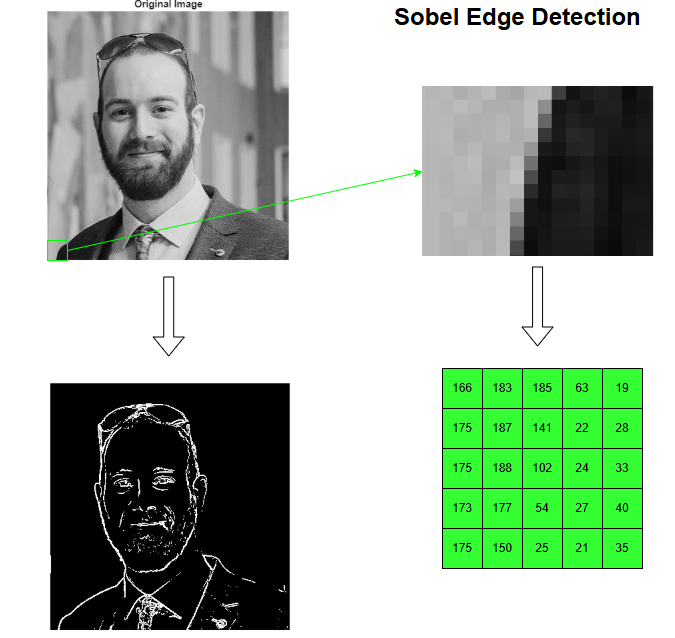

% Define image pixels
image_section = [166 183 185 63 19;
                175 187 141 22 28;
                175 188 102 24 33;
                173 177 54 27 40; 
                175 150 25 21 35]

image_section =    166   183   185    63    19
   175   187   141    22    28
   175   188   102    24    33
   173   177    54    27    40
   175   150    25    21    35



% Define Sobel filter kernels
sobel_kx = [-1 0 1; -2 0 2; -1 0 1];  % Horizontal edges
sobel_ky = [-1 -2 -1; 0 0 0; 1 2 1];  % Vertical edges

% Apply convolution to detect edges in both directions
edge_x = conv2(image_section, sobel_kx, 'valid');
edge_y = conv2(image_section, sobel_ky, 'valid');

% Combine the gradients to get edge magnitude
edge_mag = sqrt(edge_x.^2 + edge_y.^2);

% 50% of max value for threshold
max_edge_mag = max(max(edge_mag));
threshold = max_edge_mag*0.5;

% Apply threshold to create binary edge map
edge_bin = edge_mag > threshold

edge_bin = 3×3 logical array
   0   1   1
   0   1   0
   1   1   0
